%%%%%%%%%%%%%%%%%%%%%%%%%%%
%% Spidr Plots FIFA 2023 %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%

addpath('.../SpiderPlots')

folder_path='.../Counterfactuals_mat'

folder_path = '/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiFiFa/Counterfactuals_mat'

Num_classes=4;

disp('--Factual class -> 1--')

--Factual class -> 1--


counterfactuals1=load(fullfile(folder_path,"counterfactual1.mat"));
counterfactuals_cleaned1 = clean_counterfactuals(counterfactuals1.counterfactuals, Num_classes);

0/108 NOT AVAILABLE for column 2
0/108 NOT AVAILABLE for column 3
0/108 NOT AVAILABLE for column 4


disp('--Factual class -> 2--')

--Factual class -> 2--


counterfactuals2=load(fullfile(folder_path,"counterfactual2.mat"));
counterfactuals_cleaned2 = clean_counterfactuals(counterfactuals2.counterfactuals, Num_classes);

0/786 NOT AVAILABLE for column 2
0/786 NOT AVAILABLE for column 3
0/786 NOT AVAILABLE for column 4


disp('--Factual class -> 3--')

--Factual class -> 3--


counterfactuals3=load(fullfile(folder_path,"counterfactual3.mat"));
counterfactuals_cleaned3 = clean_counterfactuals(counterfactuals3.counterfactuals, Num_classes);

0/881 NOT AVAILABLE for column 2
0/881 NOT AVAILABLE for column 3
0/881 NOT AVAILABLE for column 4


disp('--Factual class -> 4--')

--Factual class -> 4--


counterfactuals4=load(fullfile(folder_path,"counterfactual4.mat"));
counterfactuals_cleaned4 = clean_counterfactuals(counterfactuals4.counterfactuals, Num_classes);

0/595 NOT AVAILABLE for column 2
0/595 NOT AVAILABLE for column 3
0/595 NOT AVAILABLE for column 4


% Remember: MF --> 1
%           DE --> 2
%           FO --> 3
%           GK --> 4

M_ind = [31,32,33,34,36,37]; 
Ph_ind = [21,22,23,24,25,27,28,29];
Sk_ind = [12,12,13,14,15,16,17,18,19,20,26,30,35,38,39];

position_index = 45;

## CLASS MF

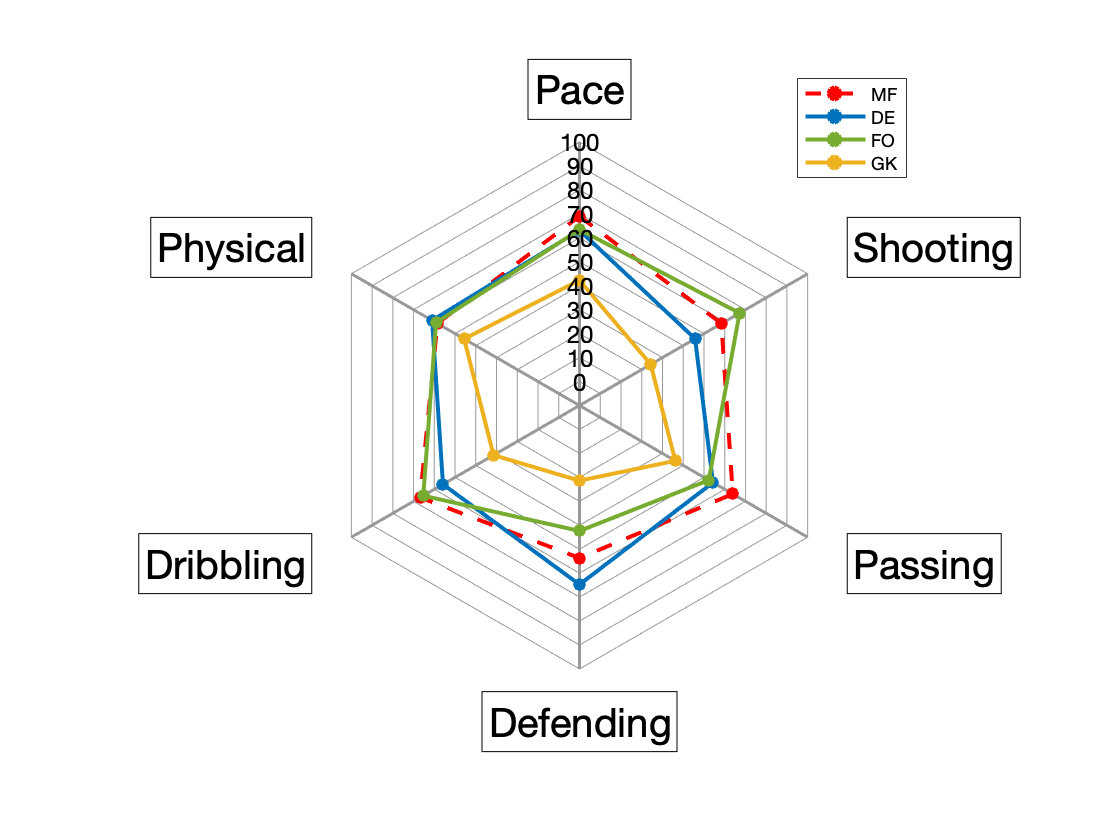

MF_counterfactuals = counterfactuals1.counterfactuals;
MF_n = size(MF_counterfactuals,1);

% matrices of factuals and counterfactuals of class MF

MF_F = [];
MF_F_class = MF_counterfactuals(:,1);

for i = 1:MF_n
    
    MF_F = [MF_F;cell2mat(MF_F_class{i}(2,:)) ];

end

MF_F = MF_F(:,1:45);

MF_DE = [];
MF_DE_class = MF_counterfactuals(:,2);

for i = 1:MF_n
    
    MF_DE = [MF_DE;cell2mat(MF_DE_class{i}(2,:)) ];

end

MF_DE = MF_DE(:,1:45);

MF_FO = [];
MF_FO_class = MF_counterfactuals(:,3);

for i = 1:MF_n
    
    MF_FO = [MF_FO;cell2mat(MF_FO_class{i}(2,:)) ];

end

MF_FO = MF_FO(:,1:45);

MF_GK = [];
MF_GK_class = MF_counterfactuals(:,4);

for i = 1:MF_n
    
    MF_GK = [MF_GK;cell2mat(MF_GK_class{i}(2,:)) ];

end

MF_GK = MF_GK(:,1:45);

% mean of factuals and counterfactuals of class MF

mu_MF_F = mean(MF_F,1);
mu_MF_DE = mean(MF_DE,1);
mu_MF_FO = mean(MF_FO,1);
mu_MF_GK = mean(MF_GK,1);

% Foundamental attributes

pace_MF_F = 0.45*mu_MF_F(21) + 0.55*mu_MF_F(22);
shooting_MF_F = 0.45*mu_MF_F(12) + 0.20*mu_MF_F(30) + 0.05*mu_MF_F(35) + 0.05*mu_MF_F(33) + 0.20*mu_MF_F(26) + 0.05*mu_MF_F(15);
passing_MF_F = 0.20*mu_MF_F(11) + 0.05*mu_MF_F(17) + 0.05*mu_MF_F(18) + 0.15*mu_MF_F(19) + 0.35*mu_MF_F(14) + 0.20*mu_MF_F(34);
defending_MF_F = 0.10*mu_MF_F(13) + 0.20*mu_MF_F(32) + 0.30*mu_MF_F(37) + 0.10*mu_MF_F(39) + 0.30*mu_MF_F(38);
dribbling_MF_F = 0.10*mu_MF_F(23) + 0.05*mu_MF_F(25) + 0.35*mu_MF_F(20) + 0.50*mu_MF_F(16);
physical_MF_F = 0.20*mu_MF_F(31) + 0.05*mu_MF_F(27) + 0.25*mu_MF_F(28) + 0.50*mu_MF_F(29);

M_mu_MF_F = [pace_MF_F, shooting_MF_F, passing_MF_F, defending_MF_F, dribbling_MF_F, physical_MF_F];

pace_MF_DE = 0.45*mu_MF_DE(21) + 0.55*mu_MF_DE(22);
shooting_MF_DE = 0.45*mu_MF_DE(12) + 0.20*mu_MF_DE(30) + 0.05*mu_MF_DE(35) + 0.05*mu_MF_DE(33) + 0.20*mu_MF_DE(26) + 0.05*mu_MF_DE(15);
passing_MF_DE = 0.20*mu_MF_DE(11) + 0.05*mu_MF_DE(17) + 0.05*mu_MF_DE(18) + 0.15*mu_MF_DE(19) + 0.35*mu_MF_DE(14) + 0.20*mu_MF_DE(34);
defending_MF_DE = 0.10*mu_MF_DE(13) + 0.20*mu_MF_DE(32) + 0.30*mu_MF_DE(37) + 0.10*mu_MF_DE(39) + 0.30*mu_MF_DE(38);
dribbling_MF_DE = 0.10*mu_MF_DE(23) + 0.05*mu_MF_DE(25) + 0.35*mu_MF_DE(20) + 0.50*mu_MF_DE(16);
physical_MF_DE = 0.20*mu_MF_DE(31) + 0.05*mu_MF_DE(27) + 0.25*mu_MF_DE(28) + 0.50*mu_MF_DE(29);

M_mu_MF_DE = [pace_MF_DE, shooting_MF_DE, passing_MF_DE, defending_MF_DE, dribbling_MF_DE, physical_MF_DE];

pace_MF_FO = 0.45*mu_MF_FO(21) + 0.55*mu_MF_FO(22);
shooting_MF_FO = 0.45*mu_MF_FO(12) + 0.20*mu_MF_FO(30) + 0.05*mu_MF_FO(35) + 0.05*mu_MF_FO(33) + 0.20*mu_MF_FO(26) + 0.05*mu_MF_FO(15);
passing_MF_FO = 0.20*mu_MF_FO(11) + 0.05*mu_MF_FO(17) + 0.05*mu_MF_FO(18) + 0.15*mu_MF_FO(19) + 0.35*mu_MF_FO(14) + 0.20*mu_MF_FO(34);
defending_MF_FO = 0.10*mu_MF_FO(13) + 0.20*mu_MF_FO(32) + 0.30*mu_MF_FO(37) + 0.10*mu_MF_FO(39) + 0.30*mu_MF_FO(38);
dribbling_MF_FO = 0.10*mu_MF_FO(23) + 0.05*mu_MF_FO(25) + 0.35*mu_MF_FO(20) + 0.50*mu_MF_FO(16);
physical_MF_FO = 0.20*mu_MF_FO(31) + 0.05*mu_MF_FO(27) + 0.25*mu_MF_FO(28) + 0.50*mu_MF_FO(29);

M_mu_MF_FO = [pace_MF_FO, shooting_MF_FO, passing_MF_FO, defending_MF_FO, dribbling_MF_FO, physical_MF_FO];

pace_MF_GK = 0.45*mu_MF_GK(21) + 0.55*mu_MF_GK(22);
shooting_MF_GK = 0.45*mu_MF_GK(12) + 0.20*mu_MF_GK(30) + 0.05*mu_MF_GK(35) + 0.05*mu_MF_GK(33) + 0.20*mu_MF_GK(26) + 0.05*mu_MF_GK(15);
passing_MF_GK = 0.20*mu_MF_GK(11) + 0.05*mu_MF_GK(17) + 0.05*mu_MF_GK(18) + 0.15*mu_MF_GK(19) + 0.35*mu_MF_GK(14) + 0.20*mu_MF_GK(34);
defending_MF_GK = 0.10*mu_MF_GK(13) + 0.20*mu_MF_GK(32) + 0.30*mu_MF_GK(37) + 0.10*mu_MF_GK(39) + 0.30*mu_MF_GK(38);
dribbling_MF_GK = 0.10*mu_MF_GK(23) + 0.05*mu_MF_GK(25) + 0.35*mu_MF_GK(20) + 0.50*mu_MF_GK(16);
physical_MF_GK = 0.20*mu_MF_GK(31) + 0.05*mu_MF_GK(27) + 0.25*mu_MF_GK(28) + 0.50*mu_MF_GK(29);

M_mu_MF_GK = [pace_MF_GK, shooting_MF_GK, passing_MF_GK, defending_MF_GK, dribbling_MF_GK, physical_MF_GK];

Min_Val = zeros(1,6);%min([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_FO; M_mu_MF_GK])-1;
Max_Val = 100*ones(1,6);%max([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_FO; M_mu_MF_GK])+1;

P = [M_mu_MF_F; M_mu_MF_DE; M_mu_MF_FO; M_mu_MF_GK];

if exist('s', 'var') % Delete variable in workspace if exists
    delete(s);
end

figure (1)
s = spider_plot_class(P); % Spider plot

s.LegendLabels = {'MF', 'DE', 'FO', 'GK'};
s.LineStyle = {'--', '-', '-','-'};
s.AxesLabels = {'Pace', 'Shooting', 'Passing', 'Defending', 'Dribbling', 'Physical'};
s.AxesInterval = 10;
s.AxesPrecision = 0;
s.AxesFontSize = 12;
s.LabelFontSize = 20;
s.LineWidth=[2, 2, 2,2];
%s.FillOption = {'on', 'on', 'on', 'on'};
%s.FillTransparency = [0.1, 0.1, 0.1, 0.1];
s.AxesLimits = [Min_Val; Max_Val];
s.AxesDisplay= 'one';
%s.AxesDisplay= 'data';
%title('Mental attributes');
s.Color = [1, 0, 0; 0 0.4470 0.7410; 0.4660 0.6740 0.1880;0.9290 0.6940 0.1250];
save_path_image = '/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiFiFa/SpiderFiFa/SpiderImages/';
name_image = 'MF_foundamental';
legend('off')
exportgraphics(gcf,strcat(strcat(save_path_image,name_image),'.png'),'Resolution',300) 

## CLASS DE

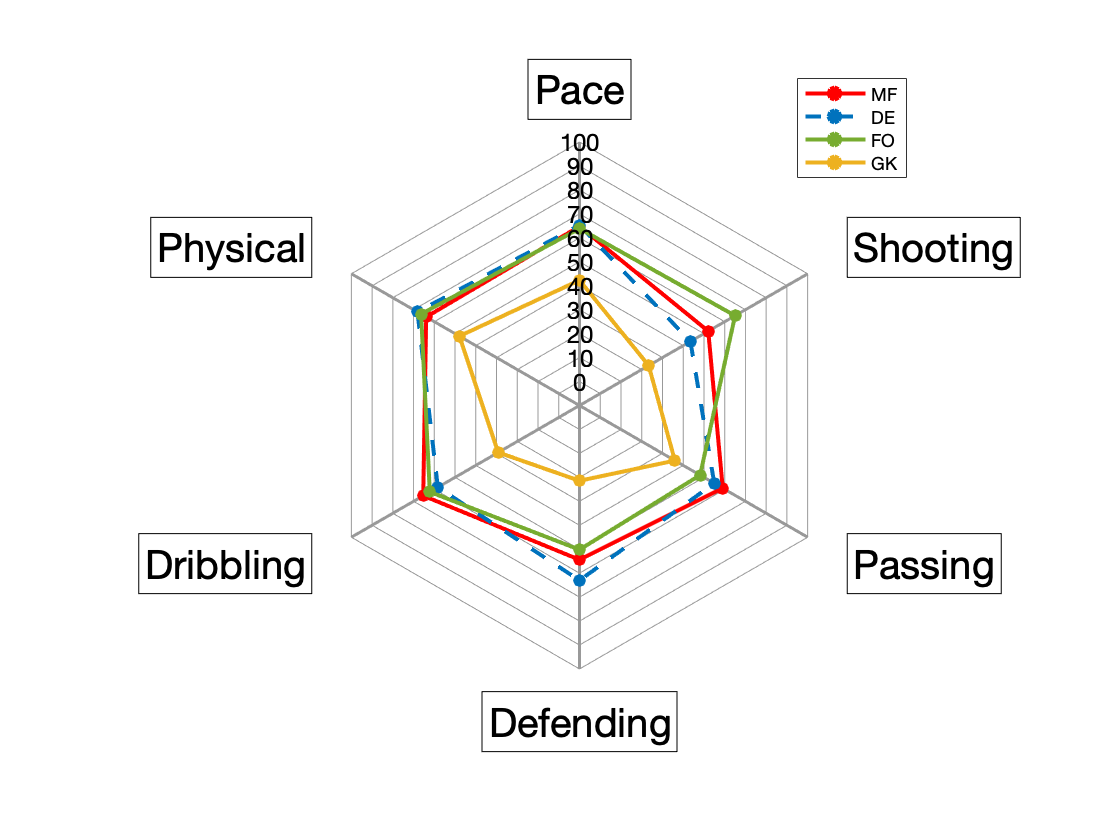

DE_counterfactuals = counterfactuals2.counterfactuals;
DE_n = size(DE_counterfactuals,1);

% matrices of factuals and counterfactuals of class MF

DE_F = [];
DE_F_class = DE_counterfactuals(:,1);

for i = 1:DE_n
    
    DE_F = [DE_F;cell2mat(DE_F_class{i}(2,:)) ];

end

DE_F = DE_F(:,1:position_index);

DE_MF = [];
DE_MF_class = DE_counterfactuals(:,2);

for i = 1:DE_n
    
    DE_MF = [DE_MF;cell2mat(DE_MF_class{i}(2,:)) ];

end

DE_MF = DE_MF(:,1:position_index);

DE_FO = [];
DE_FO_class = DE_counterfactuals(:,3);

for i = 1:DE_n
    
    DE_FO = [DE_FO;cell2mat(DE_FO_class{i}(2,:)) ];

end

DE_FO = DE_FO(:,1:position_index);

DE_GK = [];
DE_GK_class = DE_counterfactuals(:,4);

for i = 1:DE_n
    
    DE_GK = [DE_GK;cell2mat(DE_GK_class{i}(2,:)) ];

end

DE_GK = DE_GK(:,1:position_index);

% mean of factuals and counterfactuals of class MF

mu_DE_F = mean(DE_F,1);
mu_DE_MF = mean(DE_MF,1);
mu_DE_FO = mean(DE_FO,1);
mu_DE_GK = mean(DE_GK,1);


% Foundamental attributes

pace_DE_F = 0.45*mu_DE_F(21) + 0.55*mu_DE_F(22);
shooting_DE_F = 0.45*mu_DE_F(12) + 0.20*mu_DE_F(30) + 0.05*mu_DE_F(35) + 0.05*mu_DE_F(33) + 0.20*mu_DE_F(26) + 0.05*mu_DE_F(15);
passing_DE_F = 0.20*mu_DE_F(11) + 0.05*mu_DE_F(17) + 0.05*mu_DE_F(18) + 0.15*mu_DE_F(19) + 0.35*mu_DE_F(14) + 0.20*mu_DE_F(34);
defending_DE_F = 0.10*mu_DE_F(13) + 0.20*mu_DE_F(32) + 0.30*mu_DE_F(37) + 0.10*mu_DE_F(39) + 0.30*mu_DE_F(38);
dribbling_DE_F = 0.10*mu_DE_F(23) + 0.05*mu_DE_F(25) + 0.35*mu_DE_F(20) + 0.50*mu_DE_F(16);
physical_DE_F = 0.20*mu_DE_F(31) + 0.05*mu_DE_F(27) + 0.25*mu_DE_F(28) + 0.50*mu_DE_F(29);

M_mu_DE_F = [pace_DE_F, shooting_DE_F, passing_DE_F, defending_DE_F, dribbling_DE_F, physical_DE_F];

pace_DE_MF = 0.45*mu_DE_MF(21) + 0.55*mu_DE_MF(22);
shooting_DE_MF = 0.45*mu_DE_MF(12) + 0.20*mu_DE_MF(30) + 0.05*mu_DE_MF(35) + 0.05*mu_DE_MF(33) + 0.20*mu_DE_MF(26) + 0.05*mu_DE_MF(15);
passing_DE_MF = 0.20*mu_DE_MF(11) + 0.05*mu_DE_MF(17) + 0.05*mu_DE_MF(18) + 0.15*mu_DE_MF(19) + 0.35*mu_DE_MF(14) + 0.20*mu_DE_MF(34);
defending_DE_MF = 0.10*mu_DE_MF(13) + 0.20*mu_DE_MF(32) + 0.30*mu_DE_MF(37) + 0.10*mu_DE_MF(39) + 0.30*mu_DE_MF(38);
dribbling_DE_MF = 0.10*mu_DE_MF(23) + 0.05*mu_DE_MF(25) + 0.35*mu_DE_MF(20) + 0.50*mu_DE_MF(16);
physical_DE_MF = 0.20*mu_DE_MF(31) + 0.05*mu_DE_MF(27) + 0.25*mu_DE_MF(28) + 0.50*mu_DE_MF(29);

M_mu_DE_MF = [pace_DE_MF, shooting_DE_MF, passing_DE_MF, defending_DE_MF, dribbling_DE_MF, physical_DE_MF];

pace_DE_FO = 0.45*mu_DE_FO(21) + 0.55*mu_DE_FO(22);
shooting_DE_FO = 0.45*mu_DE_FO(12) + 0.20*mu_DE_FO(30) + 0.05*mu_DE_FO(35) + 0.05*mu_DE_FO(33) + 0.20*mu_DE_FO(26) + 0.05*mu_DE_FO(15);
passing_DE_FO = 0.20*mu_DE_FO(11) + 0.05*mu_DE_FO(17) + 0.05*mu_DE_FO(18) + 0.15*mu_DE_FO(19) + 0.35*mu_DE_FO(14) + 0.20*mu_DE_FO(34);
defending_DE_FO = 0.10*mu_DE_FO(13) + 0.20*mu_DE_FO(32) + 0.30*mu_DE_FO(37) + 0.10*mu_DE_FO(39) + 0.30*mu_DE_FO(38);
dribbling_DE_FO = 0.10*mu_DE_FO(23) + 0.05*mu_DE_FO(25) + 0.35*mu_DE_FO(20) + 0.50*mu_DE_FO(16);
physical_DE_FO = 0.20*mu_DE_FO(31) + 0.05*mu_DE_FO(27) + 0.25*mu_DE_FO(28) + 0.50*mu_DE_FO(29);

M_mu_DE_FO = [pace_DE_FO, shooting_DE_FO, passing_DE_FO, defending_DE_FO, dribbling_DE_FO, physical_DE_FO];

pace_DE_GK = 0.45*mu_DE_GK(21) + 0.55*mu_DE_GK(22);
shooting_DE_GK = 0.45*mu_DE_GK(12) + 0.20*mu_DE_GK(30) + 0.05*mu_DE_GK(35) + 0.05*mu_DE_GK(33) + 0.20*mu_DE_GK(26) + 0.05*mu_DE_GK(15);
passing_DE_GK = 0.20*mu_DE_GK(11) + 0.05*mu_DE_GK(17) + 0.05*mu_DE_GK(18) + 0.15*mu_DE_GK(19) + 0.35*mu_DE_GK(14) + 0.20*mu_DE_GK(34);
defending_DE_GK = 0.10*mu_DE_GK(13) + 0.20*mu_DE_GK(32) + 0.30*mu_DE_GK(37) + 0.10*mu_DE_GK(39) + 0.30*mu_DE_GK(38);
dribbling_DE_GK = 0.10*mu_DE_GK(23) + 0.05*mu_DE_GK(25) + 0.35*mu_DE_GK(20) + 0.50*mu_DE_GK(16);
physical_DE_GK = 0.20*mu_DE_GK(31) + 0.05*mu_DE_GK(27) + 0.25*mu_DE_GK(28) + 0.50*mu_DE_GK(29);

M_mu_DE_GK = [pace_DE_GK, shooting_DE_GK, passing_DE_GK, defending_DE_GK, dribbling_DE_GK, physical_DE_GK];

Min_Val = zeros(1,6);%min([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_FO; M_mu_MF_GK])-1;
Max_Val = 100*ones(1,6);%max([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_FO; M_mu_MF_GK])+1;

P = [M_mu_DE_MF; M_mu_DE_F; M_mu_DE_FO; M_mu_DE_GK];

if exist('s', 'var') % Delete variable in workspace if exists
    delete(s);
end

figure (2)
s = spider_plot_class(P); % Spider plot

s.LegendLabels = {'MF', 'DE', 'FO', 'GK'};
s.LineStyle = {'-', '--', '-','-'};
s.AxesLabels = {'Pace', 'Shooting', 'Passing', 'Defending', 'Dribbling', 'Physical'};
s.AxesInterval = 10;
s.AxesPrecision = 0;
s.AxesFontSize = 12;
s.LabelFontSize = 20;
s.LineWidth=[2, 2, 2,2];
%s.FillOption = {'on', 'on', 'on', 'on'};
%s.FillTransparency = [0.1, 0.1, 0.1, 0.1];
s.AxesLimits = [Min_Val; Max_Val];
s.AxesDisplay= 'one';
%s.AxesDisplay= 'data';
%title('Mental attributes');
s.Color = [1, 0, 0; 0 0.4470 0.7410; 0.4660 0.6740 0.1880;0.9290 0.6940 0.1250];
save_path_image = '/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiFiFa/SpiderFiFa/SpiderImages/';
name_image = 'DE_foundamental';
legend('off')
exportgraphics(gcf,strcat(strcat(save_path_image,name_image),'.png'),'Resolution',300) 

## CLASS FO

FO_counterfactuals = counterfactuals3.counterfactuals;
FO_n = size(FO_counterfactuals,1);

% matrices of factuals and counterfactuals of class MF

FO_F = [];
FO_F_class = FO_counterfactuals(:,1);

for i = 1:FO_n
    
    FO_F = [FO_F;cell2mat(FO_F_class{i}(2,:)) ];

end

FO_F = FO_F(:,1:position_index);

FO_MF = [];
FO_MF_class = FO_counterfactuals(:,2);

for i = 1:FO_n
    
    FO_MF = [FO_MF;cell2mat(FO_MF_class{i}(2,:)) ];

end

FO_MF = FO_MF(:,1:position_index);

FO_DE = [];
FO_DE_class = FO_counterfactuals(:,3);

for i = 1:FO_n
    
    FO_DE = [FO_DE;cell2mat(FO_DE_class{i}(2,:)) ];

end

FO_DE = FO_DE(:,1:position_index);

FO_GK = [];
FO_GK_class = FO_counterfactuals(:,4);

for i = 1:FO_n
    
    FO_GK = [FO_GK;cell2mat(FO_GK_class{i}(2,:)) ];

end

FO_GK = FO_GK(:,1:position_index);

% mean of factuals and counterfactuals of class MF

mu_FO_F = mean(FO_F,1);
mu_FO_MF = mean(FO_MF,1);
mu_FO_DE = mean(FO_DE,1);
mu_FO_GK = mean(FO_GK,1);

% Foundamental attributes

pace_FO_F = 0.45*mu_FO_F(21) + 0.55*mu_FO_F(22);
shooting_FO_F = 0.45*mu_FO_F(12) + 0.20*mu_FO_F(30) + 0.05*mu_FO_F(35) + 0.05*mu_FO_F(33) + 0.20*mu_FO_F(26) + 0.05*mu_FO_F(15);
passing_FO_F = 0.20*mu_FO_F(11) + 0.05*mu_FO_F(17) + 0.05*mu_FO_F(18) + 0.15*mu_FO_F(19) + 0.35*mu_FO_F(14) + 0.20*mu_FO_F(34);
defending_FO_F = 0.10*mu_FO_F(13) + 0.20*mu_FO_F(32) + 0.30*mu_FO_F(37) + 0.10*mu_FO_F(39) + 0.30*mu_FO_F(38);
dribbling_FO_F = 0.10*mu_FO_F(23) + 0.05*mu_FO_F(25) + 0.35*mu_FO_F(20) + 0.50*mu_FO_F(16);
physical_FO_F = 0.20*mu_FO_F(31) + 0.05*mu_FO_F(27) + 0.25*mu_FO_F(28) + 0.50*mu_FO_F(29);

M_mu_FO_F = [pace_FO_F, shooting_FO_F, passing_FO_F, defending_FO_F, dribbling_FO_F, physical_FO_F];

pace_FO_MF = 0.45*mu_FO_MF(21) + 0.55*mu_FO_MF(22);
shooting_FO_MF = 0.45*mu_FO_MF(12) + 0.20*mu_FO_MF(30) + 0.05*mu_FO_MF(35) + 0.05*mu_FO_MF(33) + 0.20*mu_FO_MF(26) + 0.05*mu_FO_MF(15);
passing_FO_MF = 0.20*mu_FO_MF(11) + 0.05*mu_FO_MF(17) + 0.05*mu_FO_MF(18) + 0.15*mu_FO_MF(19) + 0.35*mu_FO_MF(14) + 0.20*mu_FO_MF(34);
defending_FO_MF = 0.10*mu_FO_MF(13) + 0.20*mu_FO_MF(32) + 0.30*mu_FO_MF(37) + 0.10*mu_FO_MF(39) + 0.30*mu_FO_MF(38);
dribbling_FO_MF = 0.10*mu_FO_MF(23) + 0.05*mu_FO_MF(25) + 0.35*mu_FO_MF(20) + 0.50*mu_FO_MF(16);
physical_FO_MF = 0.20*mu_FO_MF(31) + 0.05*mu_FO_MF(27) + 0.25*mu_FO_MF(28) + 0.50*mu_FO_MF(29);

M_mu_FO_MF = [pace_FO_MF, shooting_FO_MF, passing_FO_MF, defending_FO_MF, dribbling_FO_MF, physical_FO_MF];

pace_FO_DE = 0.45*mu_FO_DE(21) + 0.55*mu_FO_DE(22);
shooting_FO_DE = 0.45*mu_FO_DE(12) + 0.20*mu_FO_DE(30) + 0.05*mu_FO_DE(35) + 0.05*mu_FO_DE(33) + 0.20*mu_FO_DE(26) + 0.05*mu_FO_DE(15);
passing_FO_DE = 0.20*mu_FO_DE(11) + 0.05*mu_FO_DE(17) + 0.05*mu_FO_DE(18) + 0.15*mu_FO_DE(19) + 0.35*mu_FO_DE(14) + 0.20*mu_FO_DE(34);
defending_FO_DE = 0.10*mu_FO_DE(13) + 0.20*mu_FO_DE(32) + 0.30*mu_FO_DE(37) + 0.10*mu_FO_DE(39) + 0.30*mu_FO_DE(38);
dribbling_FO_DE = 0.10*mu_FO_DE(23) + 0.05*mu_FO_DE(25) + 0.35*mu_FO_DE(20) + 0.50*mu_FO_DE(16);
physical_FO_DE = 0.20*mu_FO_DE(31) + 0.05*mu_FO_DE(27) + 0.25*mu_FO_DE(28) + 0.50*mu_FO_DE(29);

M_mu_FO_DE = [pace_FO_DE, shooting_FO_DE, passing_FO_DE, defending_FO_DE, dribbling_FO_DE, physical_FO_DE];

pace_FO_GK = 0.45*mu_FO_GK(21) + 0.55*mu_FO_GK(22);
shooting_FO_GK = 0.45*mu_FO_GK(12) + 0.20*mu_FO_GK(30) + 0.05*mu_FO_GK(35) + 0.05*mu_FO_GK(33) + 0.20*mu_FO_GK(26) + 0.05*mu_FO_GK(15);
passing_FO_GK = 0.20*mu_FO_GK(11) + 0.05*mu_FO_GK(17) + 0.05*mu_FO_GK(18) + 0.15*mu_FO_GK(19) + 0.35*mu_FO_GK(14) + 0.20*mu_FO_GK(34);
defending_FO_GK = 0.10*mu_FO_GK(13) + 0.20*mu_FO_GK(32) + 0.30*mu_FO_GK(37) + 0.10*mu_FO_GK(39) + 0.30*mu_FO_GK(38);
dribbling_FO_GK = 0.10*mu_FO_GK(23) + 0.05*mu_FO_GK(25) + 0.35*mu_FO_GK(20) + 0.50*mu_FO_GK(16);
physical_FO_GK = 0.20*mu_FO_GK(31) + 0.05*mu_FO_GK(27) + 0.25*mu_FO_GK(28) + 0.50*mu_FO_GK(29);

M_mu_FO_GK = [pace_FO_GK, shooting_FO_GK, passing_FO_GK, defending_FO_GK, dribbling_FO_GK, physical_FO_GK];

Min_Val = zeros(1,6);%min([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_FO; M_mu_MF_GK])-1;
Max_Val = 100*ones(1,6);%max([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_FO; M_mu_MF_GK])+1;

P = [M_mu_FO_MF; M_mu_FO_DE; M_mu_FO_F; M_mu_FO_GK];

if exist('s', 'var') % Delete variable in workspace if exists
    delete(s);
end

figure (3)
s = spider_plot_class(P); % Spider plot

s.LegendLabels = {'MF', 'DE', 'FO', 'GK'};
s.LineStyle = {'-', '-', '--','-'};
s.AxesLabels = {'Pace', 'Shooting', 'Passing', 'Defending', 'Dribbling', 'Physical'};
s.AxesInterval = 10;
s.AxesPrecision = 0;
s.AxesFontSize = 12;
s.LabelFontSize = 20;
s.LineWidth=[2, 2, 2,2];
%s.FillOption = {'on', 'on', 'on', 'on'};
%s.FillTransparency = [0.1, 0.1, 0.1, 0.1];
s.AxesLimits = [Min_Val; Max_Val];
s.AxesDisplay= 'one';
%s.AxesDisplay= 'data';
%title('Mental attributes');
s.Color = [1, 0, 0; 0 0.4470 0.7410; 0.4660 0.6740 0.1880;0.9290 0.6940 0.1250];
save_path_image = '/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiFiFa/SpiderFiFa/SpiderImages/';
name_image = 'FO_foundamental';
legend('off')
exportgraphics(gcf,strcat(strcat(save_path_image,name_image),'.png'),'Resolution',300) 

## **GK CLASS**

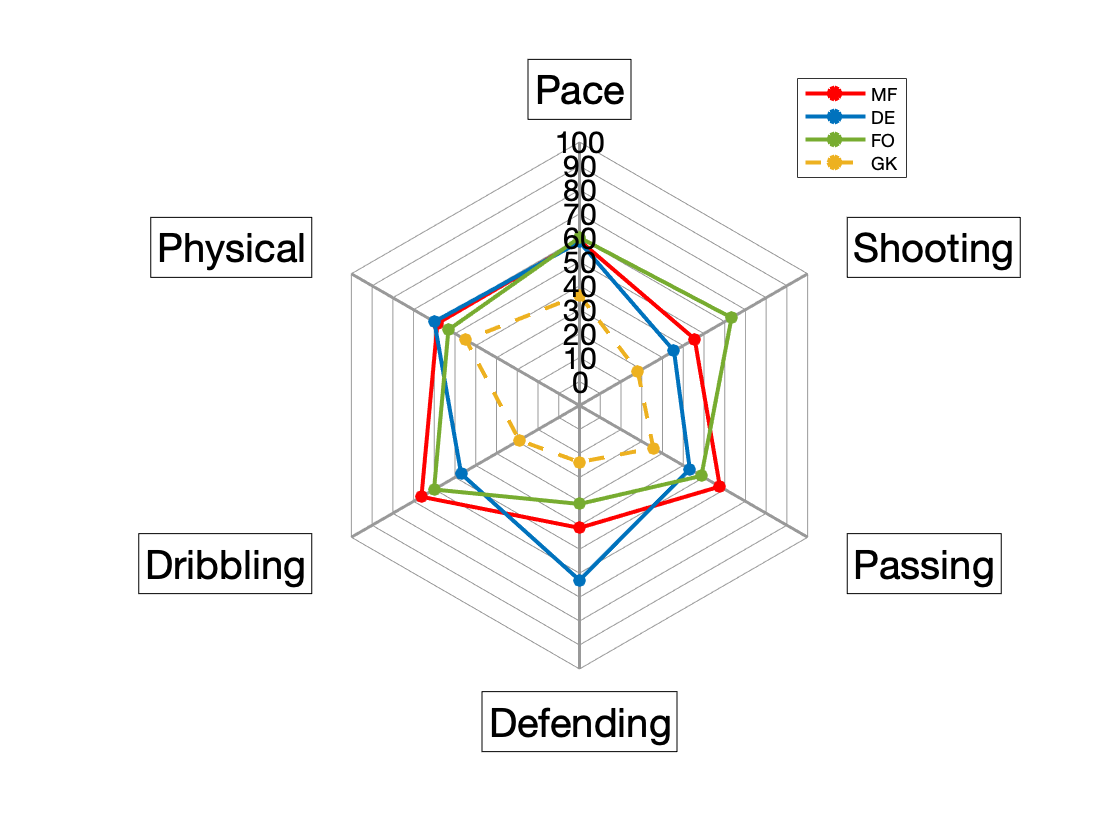

GK_counterfactuals = counterfactuals4.counterfactuals;
GK_n = size(GK_counterfactuals,1);

% matrices of factuals and counterfactuals of class MF

GK_F = [];
GK_F_class = GK_counterfactuals(:,1);

for i = 1:GK_n
    
    GK_F = [GK_F;cell2mat(GK_F_class{i}(2,:)) ];

end

GK_F = GK_F(:,1:position_index);

GK_MF = [];
GK_MF_class = GK_counterfactuals(:,2);

for i = 1:GK_n
    
    GK_MF = [GK_MF;cell2mat(GK_MF_class{i}(2,:)) ];

end

GK_MF = GK_MF(:,1:position_index);

GK_DE = [];
GK_DE_class = GK_counterfactuals(:,3);

for i = 1:GK_n
    
    GK_DE = [GK_DE;cell2mat(GK_DE_class{i}(2,:)) ];

end

GK_DE = GK_DE(:,1:position_index);

GK_FO = [];
GK_FO_class = GK_counterfactuals(:,4);

for i = 1:GK_n
    
    GK_FO = [GK_FO;cell2mat(GK_FO_class{i}(2,:)) ];

end

GK_FO = GK_FO(:,1:position_index);

% mean of factuals and counterfactuals of class MF

mu_GK_F = mean(GK_F,1);
mu_GK_MF = mean(GK_MF,1);
mu_GK_DE = mean(GK_DE,1);
mu_GK_FO = mean(GK_FO,1);

% Foundamental attributes

pace_GK_F = 0.45*mu_GK_F(21) + 0.55*mu_GK_F(22);
shooting_GK_F = 0.45*mu_GK_F(12) + 0.20*mu_GK_F(30) + 0.05*mu_GK_F(35) + 0.05*mu_GK_F(33) + 0.20*mu_GK_F(26) + 0.05*mu_GK_F(15);
passing_GK_F = 0.20*mu_GK_F(11) + 0.05*mu_GK_F(17) + 0.05*mu_GK_F(18) + 0.15*mu_GK_F(19) + 0.35*mu_GK_F(14) + 0.20*mu_GK_F(34);
defending_GK_F = 0.10*mu_GK_F(13) + 0.20*mu_GK_F(32) + 0.30*mu_GK_F(37) + 0.10*mu_GK_F(39) + 0.30*mu_GK_F(38);
dribbling_GK_F = 0.10*mu_GK_F(23) + 0.05*mu_GK_F(25) + 0.35*mu_GK_F(20) + 0.50*mu_GK_F(16);
physical_GK_F = 0.20*mu_GK_F(31) + 0.05*mu_GK_F(27) + 0.25*mu_GK_F(28) + 0.50*mu_GK_F(29);

M_mu_GK_F = [pace_GK_F, shooting_GK_F, passing_GK_F, defending_GK_F, dribbling_GK_F, physical_GK_F];

pace_GK_MF = 0.45*mu_GK_MF(21) + 0.55*mu_GK_MF(22);
shooting_GK_MF = 0.45*mu_GK_MF(12) + 0.20*mu_GK_MF(30) + 0.05*mu_GK_MF(35) + 0.05*mu_GK_MF(33) + 0.20*mu_GK_MF(26) + 0.05*mu_GK_MF(15);
passing_GK_MF = 0.20*mu_GK_MF(11) + 0.05*mu_GK_MF(17) + 0.05*mu_GK_MF(18) + 0.15*mu_GK_MF(19) + 0.35*mu_GK_MF(14) + 0.20*mu_GK_MF(34);
defending_GK_MF = 0.10*mu_GK_MF(13) + 0.20*mu_GK_MF(32) + 0.30*mu_GK_MF(37) + 0.10*mu_GK_MF(39) + 0.30*mu_GK_MF(38);
dribbling_GK_MF = 0.10*mu_GK_MF(23) + 0.05*mu_GK_MF(25) + 0.35*mu_GK_MF(20) + 0.50*mu_GK_MF(16);
physical_GK_MF = 0.20*mu_GK_MF(31) + 0.05*mu_GK_MF(27) + 0.25*mu_GK_MF(28) + 0.50*mu_GK_MF(29);

M_mu_GK_MF = [pace_GK_MF, shooting_GK_MF, passing_GK_MF, defending_GK_MF, dribbling_GK_MF, physical_GK_MF];

pace_GK_DE = 0.45*mu_GK_DE(21) + 0.55*mu_GK_DE(22);
shooting_GK_DE = 0.45*mu_GK_DE(12) + 0.20*mu_GK_DE(30) + 0.05*mu_GK_DE(35) + 0.05*mu_GK_DE(33) + 0.20*mu_GK_DE(26) + 0.05*mu_GK_DE(15);
passing_GK_DE = 0.20*mu_GK_DE(11) + 0.05*mu_GK_DE(17) + 0.05*mu_GK_DE(18) + 0.15*mu_GK_DE(19) + 0.35*mu_GK_DE(14) + 0.20*mu_GK_DE(34);
defending_GK_DE = 0.10*mu_GK_DE(13) + 0.20*mu_GK_DE(32) + 0.30*mu_GK_DE(37) + 0.10*mu_GK_DE(39) + 0.30*mu_GK_DE(38);
dribbling_GK_DE = 0.10*mu_GK_DE(23) + 0.05*mu_GK_DE(25) + 0.35*mu_GK_DE(20) + 0.50*mu_GK_DE(16);
physical_GK_DE = 0.20*mu_GK_DE(31) + 0.05*mu_GK_DE(27) + 0.25*mu_GK_DE(28) + 0.50*mu_GK_DE(29);

M_mu_GK_DE = [pace_GK_DE, shooting_GK_DE, passing_GK_DE, defending_GK_DE, dribbling_GK_DE, physical_GK_DE];

pace_GK_FO = 0.45*mu_GK_FO(21) + 0.55*mu_GK_FO(22);
shooting_GK_FO = 0.45*mu_GK_FO(12) + 0.20*mu_GK_FO(30) + 0.05*mu_GK_FO(35) + 0.05*mu_GK_FO(33) + 0.20*mu_GK_FO(26) + 0.05*mu_GK_FO(15);
passing_GK_FO = 0.20*mu_GK_FO(11) + 0.05*mu_GK_FO(17) + 0.05*mu_GK_FO(18) + 0.15*mu_GK_FO(19) + 0.35*mu_GK_FO(14) + 0.20*mu_GK_FO(34);
defending_GK_FO = 0.10*mu_GK_FO(13) + 0.20*mu_GK_FO(32) + 0.30*mu_GK_FO(37) + 0.10*mu_GK_FO(39) + 0.30*mu_GK_FO(38);
dribbling_GK_FO = 0.10*mu_GK_FO(23) + 0.05*mu_GK_FO(25) + 0.35*mu_GK_FO(20) + 0.50*mu_GK_FO(16);
physical_GK_FO = 0.20*mu_GK_FO(31) + 0.05*mu_GK_FO(27) + 0.25*mu_GK_FO(28) + 0.50*mu_GK_FO(29);

M_mu_GK_FO = [pace_GK_FO, shooting_GK_FO, passing_GK_FO, defending_GK_FO, dribbling_GK_FO, physical_GK_FO];

Min_Val = zeros(1,6);%min([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_GK; M_mu_MF_GK])-1;
Max_Val = 100*ones(1,6);%max([M_mu_MF_F; M_mu_MF_DE; M_mu_MF_GK; M_mu_MF_GK])+1;

P = [M_mu_GK_MF; M_mu_GK_DE; M_mu_GK_FO; M_mu_GK_F];

if exist('s', 'var') % Delete variable in workspace if exists
    delete(s);
end

figure (4)
s = spider_plot_class(P); % Spider plot

s.LegendLabels = {'MF', 'DE', 'FO', 'GK'};
s.LineStyle = {'-', '-', '-','--'};
s.AxesLabels = {'Pace', 'Shooting', 'Passing', 'Defending', 'Dribbling', 'Physical'};
s.AxesInterval = 10;
s.AxesPrecision = 0;
s.AxesFontSize = 15;
s.LabelFontSize = 20;
s.LineWidth=[2, 2, 2,2];
%s.FillOption = {'on', 'on', 'on', 'on'};
%s.FillTransparency = [0.1, 0.1, 0.1, 0.1];
s.AxesLimits = [Min_Val; Max_Val];
s.AxesDisplay= 'one';
%s.AxesDisplay= 'data';
%title('Mental attributes');
s.Color = [1, 0, 0; 0 0.4470 0.7410; 0.4660 0.6740 0.1880;0.9290 0.6940 0.1250];
save_path_image = '/Users/albertocarlevaro/Documents/Albi/CNR/Counterfactual/MultiCounterfactual/MultiFiFa/SpiderFiFa/SpiderImages/';
name_image = 'GK_foundamental';
legend('off')
exportgraphics(gcf,strcat(strcat(save_path_image,name_image),'.png'),'Resolution',300) 